## Fórmula Semiempírica de Masas. Obtención B/A.

function BE = BindingEnergy(A,Z)

%--------------------------------------
%
% Computes the Binding Energy making use of the semiempirical mass formula.
%
% inputs: A number of nucleons
%         Z number of protons
%
% Outputs: BE binding energy
%
%--------------------------------------

% The parameters have been taken from the book of profesor Kenneth S. Krane 
% Introduction to Nuclear Physics (formula 3.28)

av = 15.5;    % Volume coefficient (eV)
as = 16.8;    % Surface coefficient (eV)
ac = 0.72;    % Coulomb coefficient (eV)
asym = 23.0;  % Symmetry coefficient (eV)
ap = 34.0;    % Paring coefficient (eV)

% delta: (Pairing term) 

N = A-Z; % number of neutrons

if mod(Z,2) == 0 && mod(N,2) == 0
    delta = +ap * A^(-3/4);
elseif mod(Z,2) == 1 && mod(N,2) == 1
    delta = -ap * A^(-3/4);
else
    delta = 0;
end

% Binding energy terms 
aux1 = av * A - as * A^(2/3);
aux2 = -ac * Z * (Z - 1) * A^(-1/3);
aux3 = -asym * (A - 2*Z)^2 / A;

% Total binding energy 
BE = aux1 + aux2 + aux3 + delta;
end


A continuación hacemos una gráfica de la energía de enlace por nucleón de los isótopos más representativos.

Lista de nucleos:

% Lista de núcleos estables (A, Z, símbolo)
nucleos = {
    2,    1,  '²H';
    4,    2,  '⁴He';
    6,    3,  '⁶Li';
    9,    4,  '⁹Be';
    11,   5,  '¹¹B';
    12,   6,  '¹²C';
    14,   7,  '¹⁴N';
    19,   9,  '¹⁹F';
    20,  10,  '²⁰Ne';
    35,  17,  '³⁵Cl';
    56,  26,  '⁵⁶Fe';
    75,  33,  '⁷⁵As';
    89,  39,  '⁸⁹Y';
    100, 42,  '¹⁰⁰Mo';
    110, 48,  '¹¹⁰Cd';
    126, 52,  '¹²⁶Te';
    141, 59,  '¹⁴¹Pr';
    160, 66,  '¹⁶⁰Dy';
    180, 72,  '¹⁸⁰Hf';
    197, 79,  '¹⁹⁷Au';
    209, 83,  '²⁰⁹Bi';
    238, 92,  '²³⁸U';
};


Gráficamos la función:

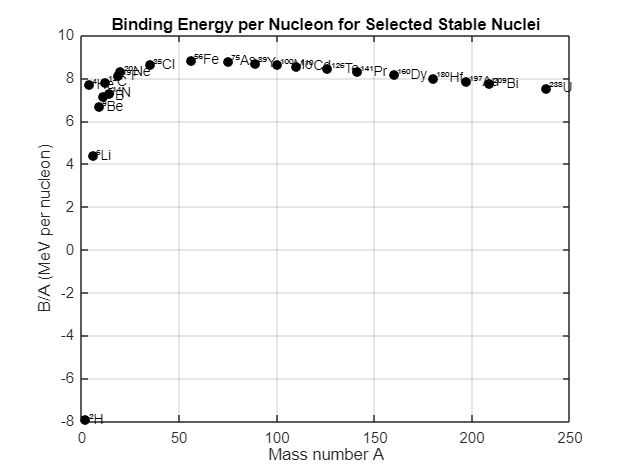

% Prealocar vectores
A_vals = cell2mat(nucleos(:,1));
Z_vals = cell2mat(nucleos(:,2));
labels = nucleos(:,3);
BE_vals = zeros(size(A_vals));
BE_per_A = zeros(size(A_vals));

% Calcular energía de enlace por nucleón
for i = 1:length(A_vals)
    A = A_vals(i);
    Z = Z_vals(i);
    BE = BindingEnergy(A,Z);
    BE_vals(i) = BE;
    BE_per_A(i) = BE / A;
end

% Graficar
figure;
plot(A_vals, BE_per_A, 'ko', 'MarkerFaceColor', 'k');
xlabel('Mass number A');
ylabel('B/A (MeV per nucleon)');
title('Binding Energy per Nucleon for Selected Stable Nuclei');
grid on;

% Añadir etiquetas
hold on;
for i = 1:length(A_vals)
    text(A_vals(i) + 1.5, BE_per_A(i), labels{i}, 'FontSize', 9);
end
hold off;